# Slope fields

## Introduction

Suppose we have a first-order differential equation of the form


$$y^{\prime}=f(x,y)$$


where $f(x,y)$ is some expression in $x$ and $y$. The differential equation says that the slope of a solution curve at a point $(x,y)$ on the curve is $f(x,y)$. If we draw short line segments with slope $f(x,y)$ at several points $(x,y)$, the result is called a **slope field** (or direction field). 

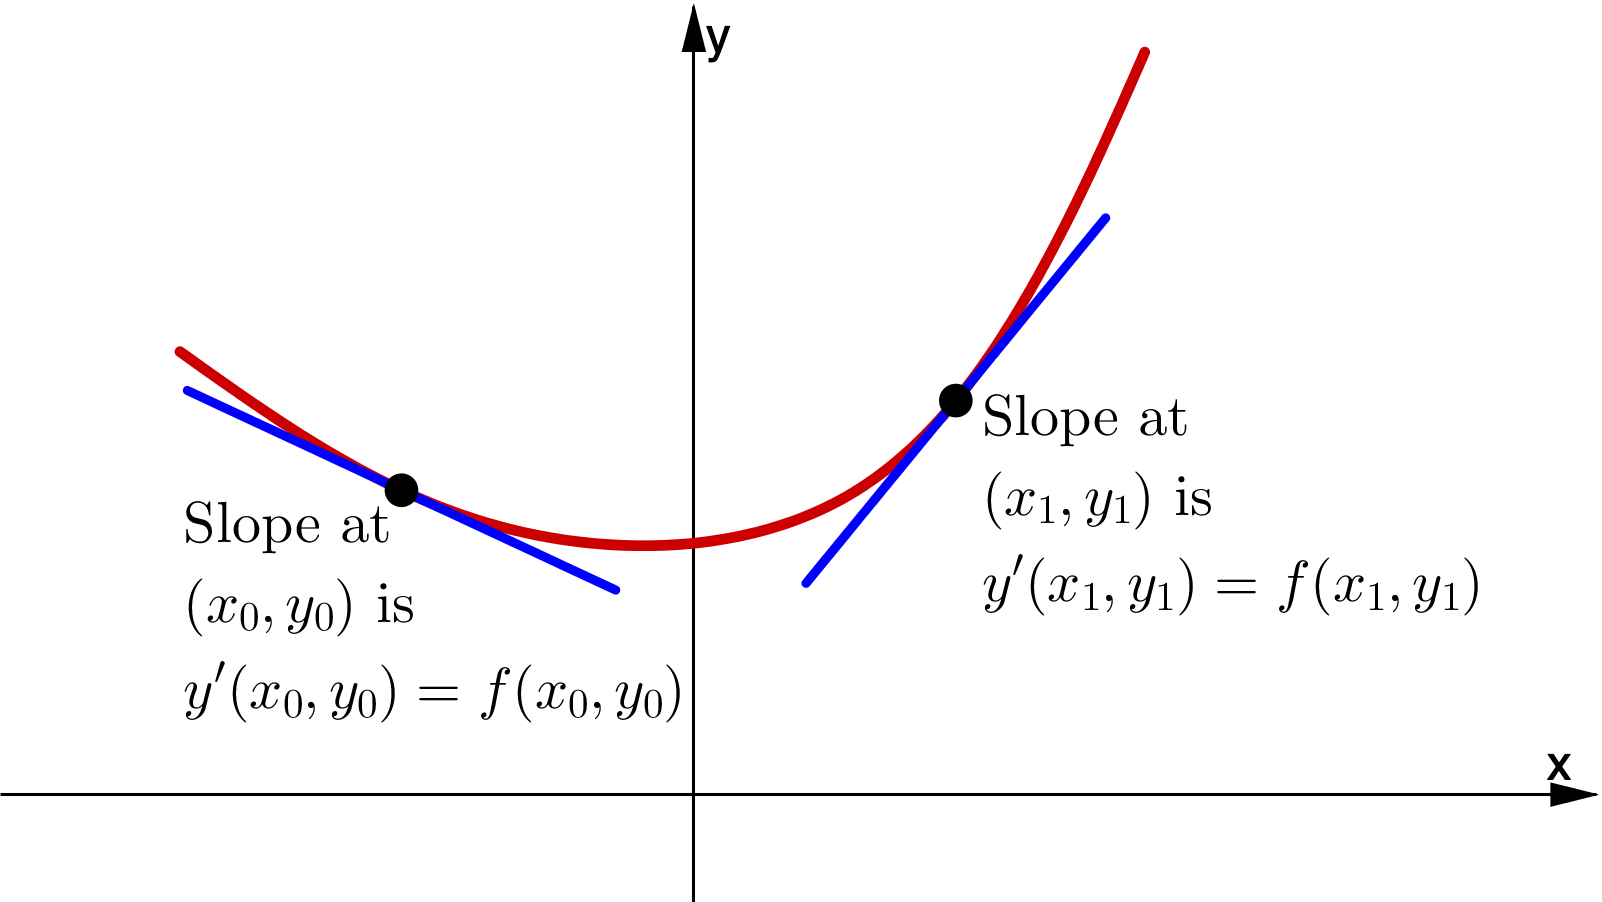

These line segments indicate the direction in which a solution curve is heading, so the direction field helps us visualise the general shape of these curves.

In this activity we will explore the basic commands used to plot slope fields that will help you to analyse solution curves of first-order differential equations.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

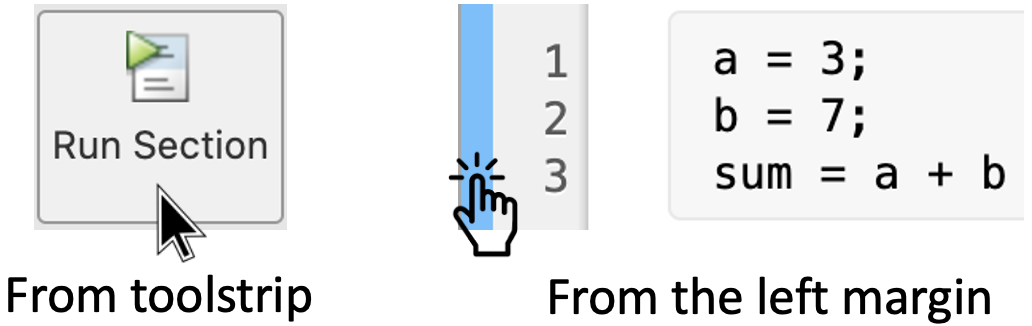

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Drawing vectors in MATLAB

### 1.1 Drawing single vectors

To start plotting slope fields first we need to learn how to plot vectors. For example, consider the vector $v$ starting from the point $P=(1,3)$ to the point $Q=(2,10)$. Thus, we have that 

$v=\left(\begin{array}{c}2-1\\10-3\end{array}\right)
=\left(\begin{array}{c}1\\7\end{array}\right)$.

An easy way to plot this vector in MATLAB is using the command 

[`quiver(X, Y, U, V)`](https://au.mathworks.com/help/matlab/ref/quiver.html)

which plots arrows with [*directional components*](http://mathonline.wikidot.com/determining-a-vector-given-two-points#toc1) `U` and `V` at the Cartesian coordinates specified by `X` and `Y`.

For example, the following code plot vector $v$. Just run this section to see the plot.

% Define starting point in cartesian coordinates
X = 1;
Y = 3;
% Define directional components
U = 1;
V = 7;
quiver(X, Y, U, V)
% The following line sets the axis limits with grid "on"
axis([-10 10 -10 10]), grid on

**Remark 1:** Observe that by default, the `quiver` function scales the arrow lengths so that they do not overlap, in case you plot many vectors at the same time. Also, the limits of the axis were added to improve the visualisation. Delete the last line from the previous code and re-run this section to see what happens.

### 1.2 Drawing multiple vectors

If we want to plot multiple vectors at the same time, then we can use the following code:

% Define starting point in cartesian coordinates
X1 = -1;
Y1 = 2;
% Define directional components
U1 = -2;
V1 = 3;
quiver(X1, Y1, U1, V1)
hold on
% Define starting point in cartesian coordinates
X2 = 2;
Y2 = 1;
% Define directional components
U2 = -2;
V2 = -4;
quiver(X2, Y2, U2, V2) 
hold off
% Set axis limits with grid "on"
axis([-6 6 -6 6]), grid on

Play around with the previous code. Change the cartesian coordinates and directional components of each vector. Plot a third vector. Re-run this section to see the results.

**Remark 2:** The command [`hold on`](https://au.mathworks.com/help/matlab/ref/hold.html) retains plots in the current axes so that new plots added to the axes do not delete existing plots.

## 2. Drawing vectors of a slope field

### 2.1 How it works

Consider the differential equation


$$\frac{dy}{dx}=x^2+y^2-1$$


To draw a slope field in the region $[-3,3]\times[-3,3]$ requires the following steps.

**Step 1)** First we need to define a two-dimensional grid of equally spaced points, like the one shown in the Figure below:

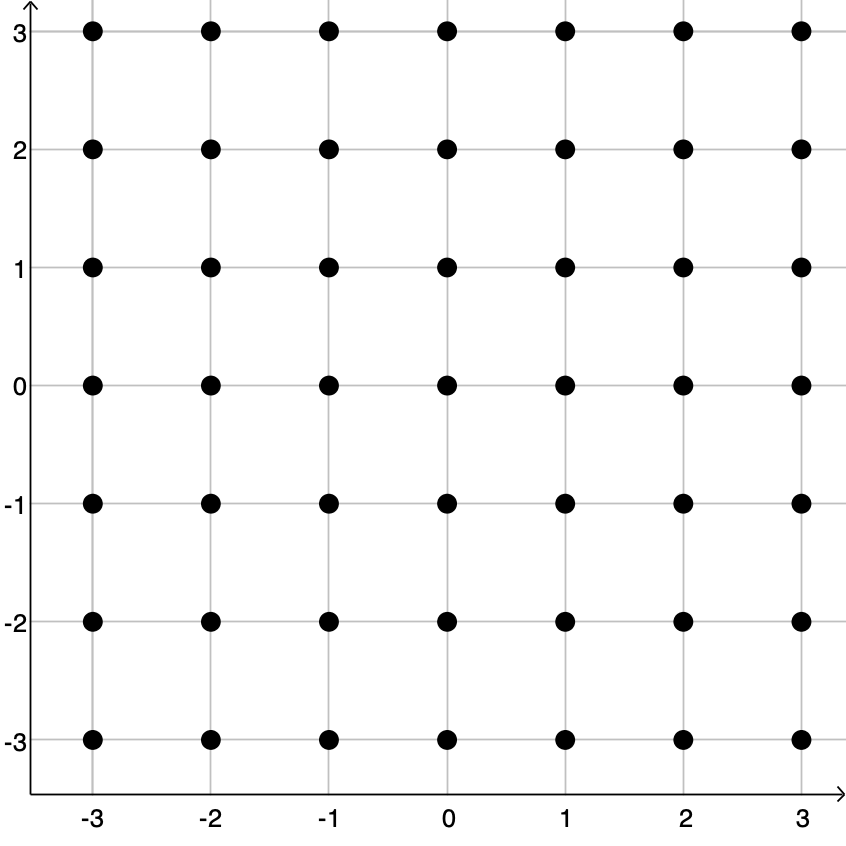

This can be done with the following code:

Observe that for smaller values of the variable `spacing` we will get more points in our grid.

The syntax `[x, y]` denotes an array of two matrices `x` and `y` that will contain the $x,y$ coordinates of the points in our grid, respectively. So the expression 

[`[x, y] = meshgrid(-3:spacing:3)`](https://au.mathworks.com/help/matlab/ref/meshgrid.html)

will return 2-D grid coordinates based on the coordinates contained in vectors `-3` and `3` separated by 1 unit, the value of `spacing`. That is: 

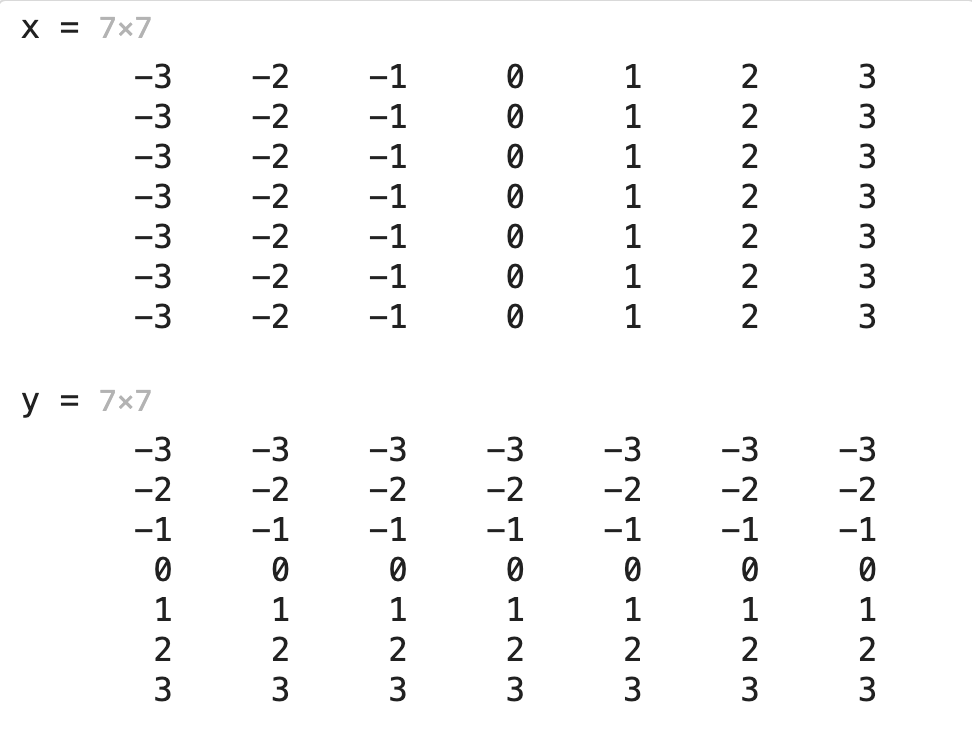

**Step 2)** We need to define a variable `dydx` for the slope at each point as follows:

**Remark 3:** Here we are using row vectors (also known as *arrays*) which means that the operations *multiplication*, *division* and *exponentiation* must have the *period *"`.`" before each operator: `*, /, ^`. Learn more about it here: [Arithmetic operations](https://au.mathworks.com/help/matlab/arithmetic-operators.html).

**Step 3)** Finally, we need to calculate the [*directional components*](http://mathonline.wikidot.com/determining-a-vector-given-two-points) of each slope vector. The slope is determined by the differential equation. So, if we choose a point $(x_0,y_0)$ from our grid, and assuming a horizontal spacing of 1 unit is adequate, we should arrive at something like the following:

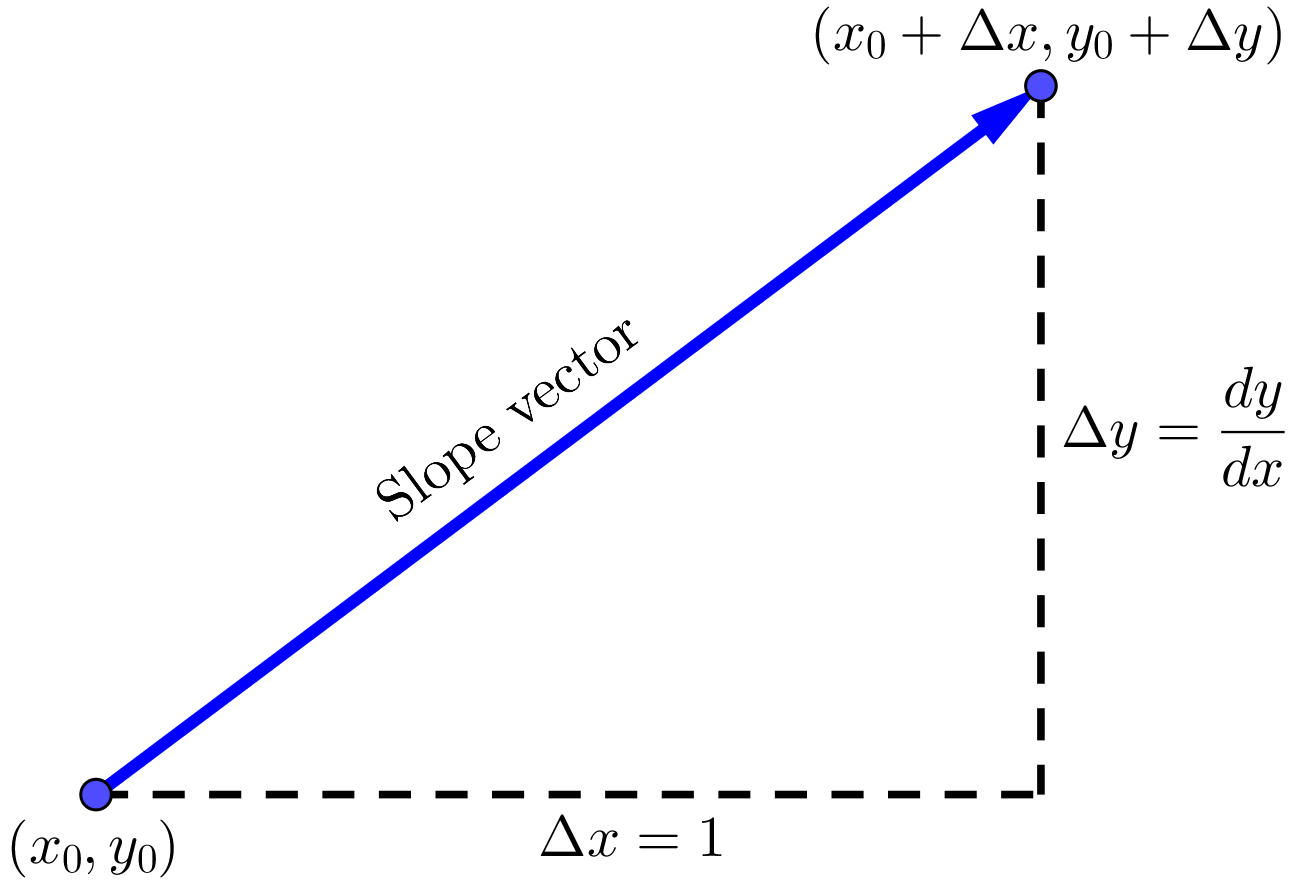

Thus the *directional components* of the slope vector starting at $(x_0,y_0)$ are: $\Delta x$ and $\Delta y$. Therefore, we have


$$\text{slope vector} 
=\left(\begin{array}{c}\Delta x\\\Delta y\end{array}\right)=\left(\begin{array}{c}\Delta x\\dy/dx\end{array}\right)$$


As it stands, this slope vector will be in contact with the other vectors in our grid, thus, for a clearer visualization of the slope field we can simply shorten its length. If we divide the slope vector by its length given by

$h =\sqrt{\Delta x^2+ \Delta y ^2}=\sqrt{\Delta x^2+(dy/dx)^2}$,

then we obtain

$\text{unit slope vector} =\left(\begin{array}{c}\frac{\Delta x}{h}\\ \frac{dy/dx}{h}\end{array}\right)$.

Then the same procedure is applied to every point in our grid to obtain the slope field.

### 2.2 MATLAB code to plot slop fields

Now we are ready to plot our slope field. Run this section to see the result of the following code:

% Initialise grid domain.
spacing = 0.5;
[x, y] = meshgrid(-3:spacing:3);
 
% Define the derivative.
dydx = x.^2 + y.^2 - 1;

% Define "delta x" and the length of the slope vectors
deltax = 1;
h = sqrt(deltax^2 + dydx.^2); 

% Note: Observe that "deltax" is a number so we don't  
% need the period "." before the operator "^".
 
% Define the directional components of slope vectors
% with a scale factor for better visualisation.
Dx = deltax./ h;
Dy = dydx./ h;
 
% Plot slope field using quiver 
% with a given "scale", and no arrowheads
scale = 0.5;
quiver(x, y, Dx, Dy, scale, 'showArrowHead', 'off');
 
% Set axis limits
axis([-3.5 3.5 -3.5 3.5])

What do you notice? What do you wonder? What happens if you change the values of the variables `spacing`, `deltax` and `scale`?

## 2. Hands on Practice

It is time to apply what we have just learnt. 

#### Activity:

Recycle the code from section 2.2 to plot the slope field for each one of the following differential equations:

- 
$$y'=x(2-y)$$


- 
$$y'=x+y-1$$


- 
$$y'=x^2y-\frac{1}{2}y^2$$


- 
$$y'=\sin x\cos y$$


**Hints: **

- Use different variables (name them carefully) for each differential equation.

- If you want to try a different format for the slope field, consult the documentation of the command [`quiver()`](https://au.mathworks.com/help/matlab/ref/quiver.html).

**Part 1.** Write your code here:

**Part 2.** Write your code here:

**Part 3.** Write your code here:

**Part 4.** Write your code here: